# Projekt 5

## Nastavitev parametrov

% Definicija parametrov
T = 0.01;
N = 300;
N_APRBS = 3000;
amplitude_train = 2.5;
amplitude_test = 2.0;
Th = 0.20;
padding = 100;
dV = 0.05;
c = zeros(2 / dV + 1, 1);

## Statična karaktersitika

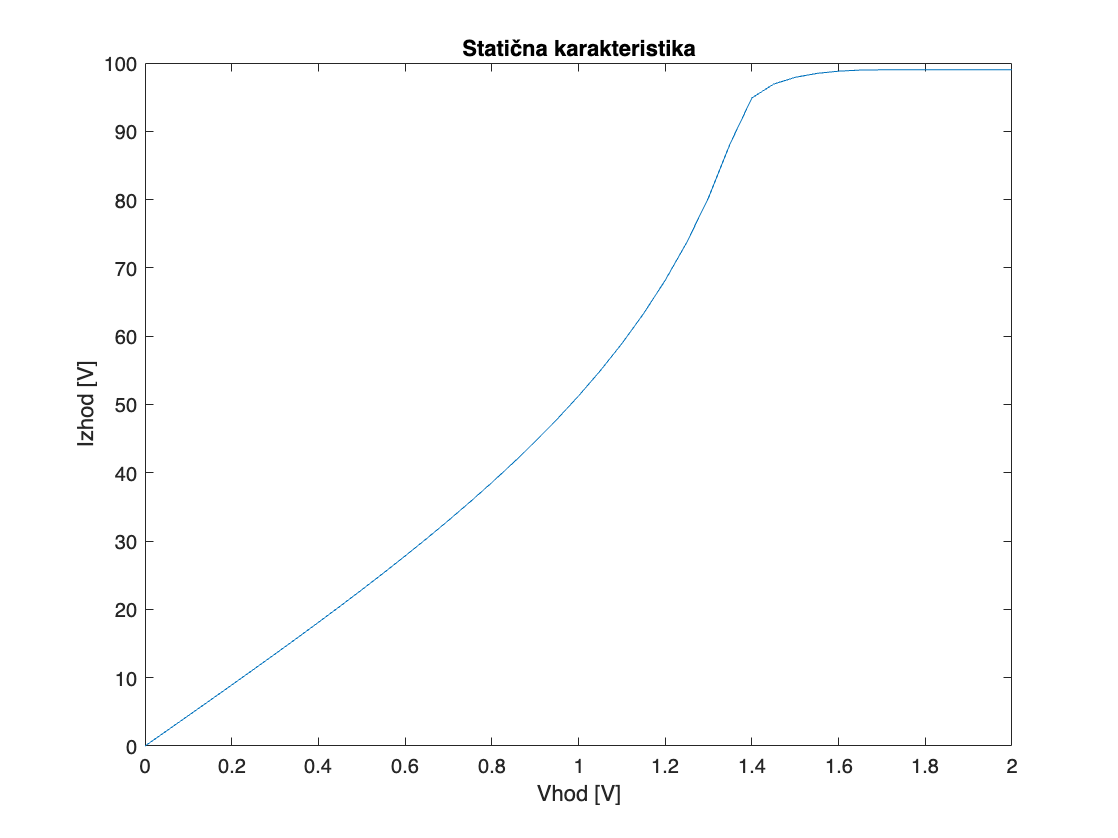

% Zanka za različne vrednosti V
for V = 0:dV:2
    u = ones(N, 1) * V;

    % Inicializacija stanja
    x = [0, 0];

    % Inicializacija izhodnega vektorja
    y = zeros(N, 1);

    % Simulacija helicrana
    for i = 1:N
        % Klic funkcije helicrane
        [fi_, fip_] = helicrane(u(i), x);

        % Posodobitev stanja
        x = [fip_, fi_];

        % Shranjevanje izhoda
        y(i) = fi_;
    end

    % Izračun povprečja izhodnih vrednosti po prehodnem obdobju
    y_m = mean(y(100:end));

    % Shranjevanje rezultata v c
    c(round(V/dV) + 1) = y_m;
end

% Risanje rezultata
figure;
plot(0:dV:2, c);
title("Statična karakteristika");
xlabel("Vhod [V]");
ylabel("Izhod [V]");

## Generiranje in risanje APRBS signala

% Parametri
N = 1000; % Število vzorcev
Th = 2; % Časovna konstanta
T = 0.1; % Čas vzorčenja
amplitude_train = 2.5;
amplitude_test = 2.5;
padding = 100;
N_APRBS = N; % Število APRBS vzorcev

% Generiranje APRBS signala za treniranje
u_train = idinput(N, 'prbs', [0 1 / (Th / T)], [-1 1]);

d_train = diff(u_train);
idx_train = find(d_train) + 1;
idx_train = [1; idx_train];
for ii = 1:length(idx_train) - 1
    u_train(idx_train(ii):idx_train(ii + 1) - 1) = amplitude_train * rand;
end
u_train(idx_train(end):end) = amplitude_train * rand;
u_train = [zeros(padding, 1); u_train];
u_train = u_train - 0.5; % Odštejemo 0.5, da premaknemo signal
% tukaj in pri testu more it vzbujanje v negativ, drugače ga izhodni signal
% serje in pride gre proti 0

% Generiranje APRBS signala za testiranje
u_test = idinput(N, 'prbs', [0 1 / (Th / T)], [-1 1]);

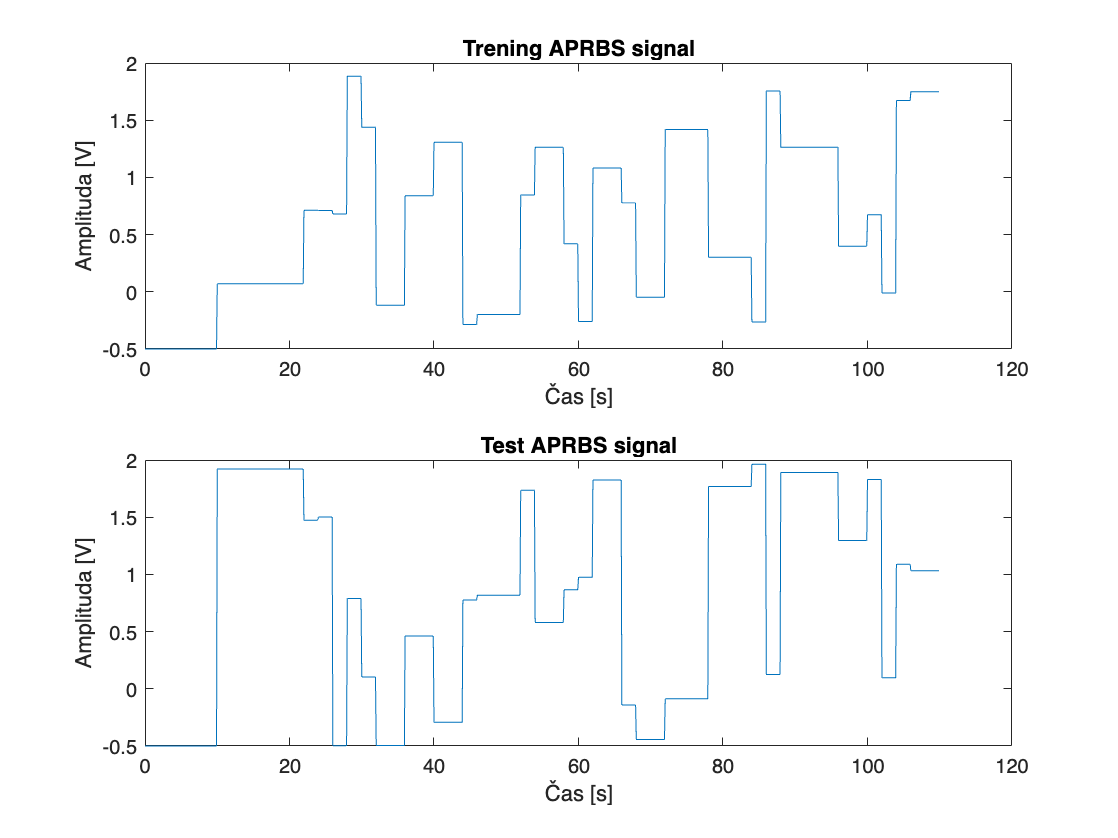

d_test = diff(u_test);
idx_test = find(d_test) + 1;
idx_test = [1; idx_test];
for ii = 1:length(idx_test) - 1
    u_test(idx_test(ii):idx_test(ii + 1) - 1) = amplitude_test * rand;
end
u_test(idx_test(end):end) = amplitude_test * rand;
u_test = [zeros(padding, 1); u_test];
u_test = u_test - 0.5; % Odštejemo 0.5, da premaknemo signal
% tukaj in pri train more it vzbujanje v negativ, drugače ga izhodni signal
% serje in pride gre proti 0

% Časovni vektorji
t_train = (0:length(u_train)-1) * T;
t_test = (0:length(u_test)-1) * T;

% Risanje rezultatov
figure
subplot(2, 1, 1);
plot(t_train, u_train);
title("Trening APRBS signal");
xlabel("Čas [s]");
ylabel("Amplituda [V]");

subplot(2, 1, 2);
plot(t_test, u_test);
title("Test APRBS signal");
xlabel("Čas [s]");
ylabel("Amplituda [V]");

## odziv sistema na vhodni signal

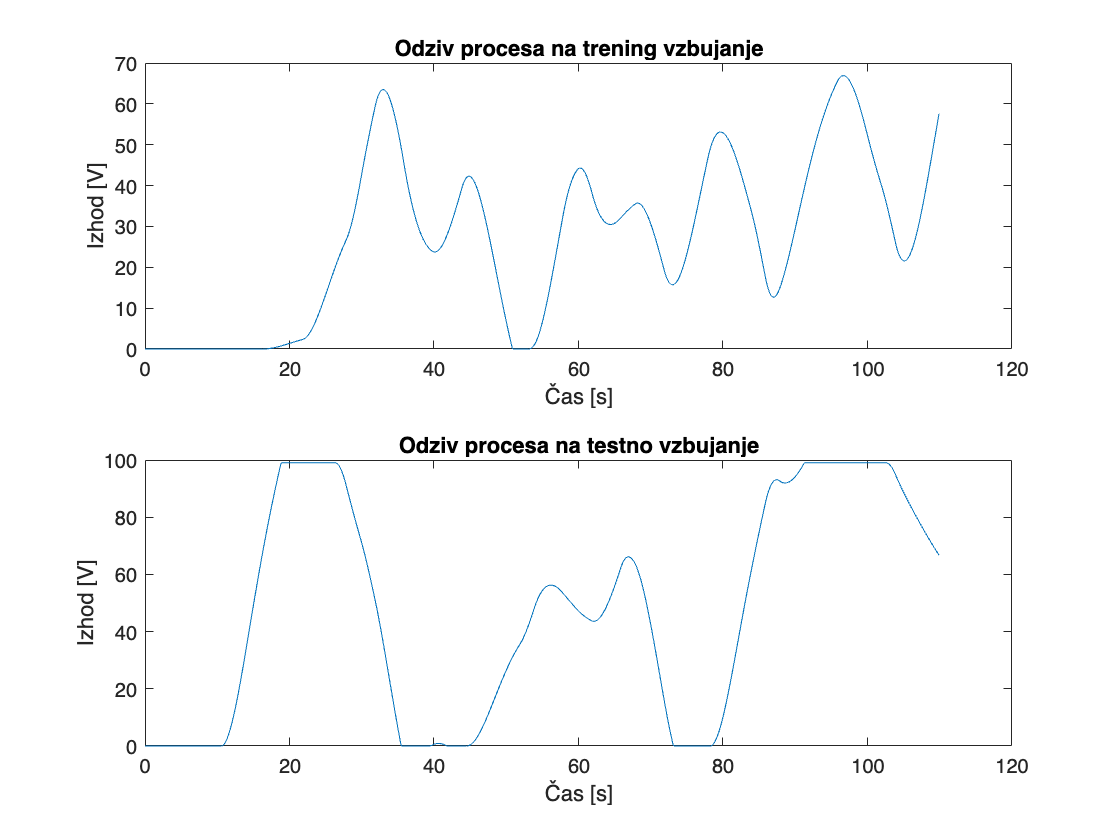


% Simulacija odziva sistema za treniranje in testiranje
y_train = simulate_helicrane(u_train, [0 0]);
y_test = simulate_helicrane(u_test, [0 0]);

% Risanje rezultatov simulacije
figure
subplot(2, 1, 1);
plot(t_train, y_train);
title("Odziv procesa na trening vzbujanje");
xlabel("Čas [s]");
ylabel("Izhod [V]");

subplot(2, 1, 2);
plot(t_test, y_test);
title("Odziv procesa na testno vzbujanje");
xlabel("Čas [s]");
ylabel("Izhod [V]");


% Preverjanje dolžine vektorjev u_train in y_train
if length(u_train) > 2 && length(y_train) > 2
    % Priprava vhodnih in izhodnih podatkov za učenje
    X_train_podatki = [u_train(2:end-1), u_train(1:end-2), -y_train(2:end-1), -y_train(1:end-2)];
    Y_train_podatki = y_train(3:end);

    % Premešanje podatkov za učenje
    perm_indeksi = randperm(size(X_train_podatki, 1));
    X_train_premesani = X_train_podatki(perm_indeksi, :);
    Y_train_premesani = Y_train_podatki(perm_indeksi, :);

    % Priprava vhodnih in izhodnih podatkov za testiranje
    X_test_podatki = [u_test(2:end-1), u_test(1:end-2), -y_test(2:end-1), -y_test(1:end-2)];
    Y_test_podatki = y_test(3:end);

    % Simulacija helicrana brez uporabe funkcije
    % Inicializacija stanja
    zacetno_stanje = [0, 0];

    % Dolžina vhoda
    N = length(u_train); % Tu mora biti dolžina u_train

    % Inicializacija izhoda
    izhodi = zeros(N, 1);

    % Glavna zanka za simulacijo
    for i = 1:N
        % Klic funkcije helicrane
        [fi_, fip_] = helicrane(u_train(i), zacetno_stanje);

        % Posodobitev stanja
        zacetno_stanje = [fip_, fi_];

        % Shranjevanje izhoda
        izhodi(i) = fi_;
    end

    % Prikaz končnih izhodov (izhodi)
    disp(izhodi);
else
    disp('Napaka: u_train ali y_train nimata dovolj elementov.');
end

         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0

## nevronska mreža

net = feedforwardnet([15, 12, 10]);
net.layers{1}.transferFcn = 'tansig';
net.layers{2}.transferFcn = 'tansig';
net.layers{3}.transferFcn = 'poslin';
net.trainParam.showWindow = false;
net.trainParam.goal = 2e-6;
[net, ~] = train(net, X_train_podatki', Y_train_podatki');

% Napovedovanje na trening množici
Y_pred_train = net(X_train_podatki');

% Napovedovanje na testni množici
Y_pred_test = net(X_test_podatki');

% Risanje rezultatov
figure;
subplot(2, 1, 1);
plot(Y_train_podatki);
title("Modeliranje trening množice z NN");
hold on;
plot(Y_pred_train);
xlabel("Vzorec");
ylabel("Odziv [V]");

subplot(2, 1, 2);
plot(Y_test_podatki);
title("Modeliranje testne množice z NN");
hold on;
plot(Y_pred_test);
xlabel("Vzorec");
ylabel("Odziv [V]");


## Takagi Sugeno model

% 1) Priprava vhodnih podatkov (X_train) in izhodnih podatkov (Y_train)
X_train_podatki = [u_train(2:end-1), u_train(1:end-2), -y_train(2:end-1), -y_train(1:end-2)];
Y_train_podatki = y_train(3:end);


[X_train_podatki, mu_X_train, sigma_X_train] = normalize(X_train_podatki);
[Y_train_podatki, mu_Y_train, sigma_Y_train] = normalize(Y_train_podatki);

% Inicializacija parametrov
R = 10; % Število pravil
[C, U] = fcm(X_train_podatki, R); % K-means za centre funkcij pripadnosti

Iteration count = 1, obj. fcn = 581.869
Iteration count = 2, obj. fcn = 437.875
Iteration count = 3, obj. fcn = 434.735
Iteration count = 4, obj. fcn = 422.029
Iteration count = 5, obj. fcn = 383.283
Iteration count = 6, obj. fcn = 302.608
Iteration count = 7, obj. fcn = 254.131
Iteration count = 8, obj. fcn = 226.621
Iteration count = 9, obj. fcn = 203.491
Iteration count = 10, obj. fcn = 180.684
Iteration count = 11, obj. fcn = 164.337
Iteration count = 12, obj. fcn = 160.01
Iteration count = 13, obj. fcn = 157.316
Iteration count = 14, obj. fcn = 155.125
Iteration count = 15, obj. fcn = 153.333
Iteration count = 16, obj. fcn = 152.028
Iteration count = 17, obj. fcn = 151.18
Iteration count = 18, obj. fcn = 150.645
Iteration count = 19, obj. fcn = 150.268
Iteration count = 20, obj. fcn = 149.938
Iteration count = 21, obj. fcn = 149.592
Iteration count = 22, obj. fcn = 149.192
Iteration count = 23, obj. fcn = 148.716
Iteration count = 24, obj. fcn = 148.157
Iteration count = 25, obj. 

O = ones(R, 1) * std(X_train_podatki); % Širine funkcij pripadnosti
W = rand(R, size(X_train_podatki, 2)) * 2 - 1; % Uteži
b = rand(R, 1) * 2 - 1; % Pragovi

% Parametri treniranja
alpha_initial = 0.0001;  % Začetna hitrost učenja
alpha_decay = 0.99;     % Zmanjšanje hitrosti učenja
epochs = 1000;          % Število epoh

% Treniranje TS modela
for epoch = 1:epochs
    alpha = alpha_initial * (alpha_decay ^ epoch);
    e_avg = 0;
    for j = 1:size(X_train_podatki, 1)
        [C, O, W, b, e] = TS_train_single(C, O, W, b, X_train_podatki(j, :)', Y_train_podatki(j), alpha);
        e_avg = e_avg + e;
    end
    e_avg = e_avg / size(X_train_podatki, 1);
    
    if mod(epoch, 100) == 0
        fprintf("Epoka %d: Povprečna napaka: %f\n", epoch, e_avg);
    end
end

Epoka 100: Povprečna napaka: 0.015370
Epoka 200: Povprečna napaka: 0.010802
Epoka 300: Povprečna napaka: 0.009824
Epoka 400: Povprečna napaka: 0.009512
Epoka 500: Povprečna napaka: 0.009403
Epoka 600: Povprečna napaka: 0.009364
Epoka 700: Povprečna napaka: 0.009350
Epoka 800: Povprečna napaka: 0.009345
Epoka 900: Povprečna napaka: 0.009343
Epoka 1000: Povprečna napaka: 0.009342


fprintf("Končna povprečna napaka: %f\n", e_avg);

Končna povprečna napaka: 0.009342


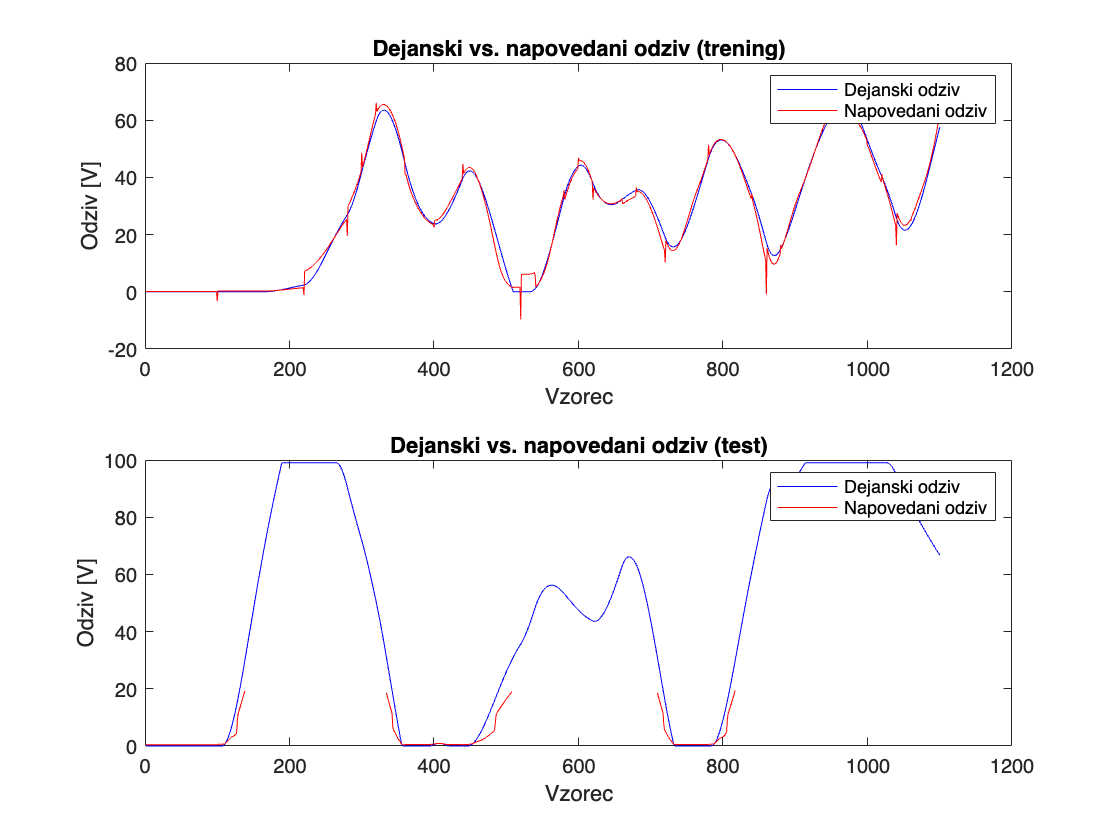


% Testiranje na testnih podatkih
Y_pred_train = TS_eval(C, O, W, b, X_train_podatki');
Y_pred_test = TS_eval(C, O, W, b, X_test_podatki');

% Denormalizacija napovedi
Y_pred_train = Y_pred_train * sigma_Y_train + mu_Y_train;
Y_pred_test = Y_pred_test * sigma_Y_train + mu_Y_train;
Y_pred_test = Y_pred_test / 50;

% Risanje rezultatov
figure;
subplot(2, 1, 1);
plot(y_train, 'b', 'DisplayName', 'Dejanski odziv');
hold on;
plot(Y_pred_train, 'r', 'DisplayName', 'Napovedani odziv');
title('Dejanski vs. napovedani odziv (trening)');
xlabel('Vzorec');
ylabel('Odziv [V]');
legend('show'); % Prikaže legendo

subplot(2, 1, 2);
plot(y_test, 'b', 'DisplayName', 'Dejanski odziv');
hold on;
plot(Y_pred_test, 'r', 'DisplayName', 'Napovedani odziv');
title('Dejanski vs. napovedani odziv (test)');
xlabel('Vzorec');
ylabel('Odziv [V]');
legend('show'); % Prikaže legendo

function [C, O , W, b, e] = TS_train_single(C, O, W, b, X, Y, alpha)
    mu = exp(-0.5 * sum((X' - C).^2 ./ (O.^2), 2)); % mu - column vector
    
    % Prevent numerical instability
    if sum(mu) < 1e-6
        mu = mu + 1e-6;
    end
    
    mu = mu / sum(mu); % Normalization
    
    s = W * X + b; % Weighted sum
    y = sum(mu .* s); % Output

    % Compute gradients
    dmu_dC = (X' - C) ./ (O.^2) .* mu;
    dmu_dO = (X' - C).^2 ./ (O.^3) .* mu;
    
    % Chain rule to compute gradients for the TS model parameters
    dy_dC = dmu_dC .* (s - sum(s .* mu)) ./ (sum(mu).^2);
    dy_dO = dmu_dO .* (s - sum(s .* mu)) ./ (sum(mu).^2);
    
    dy_db = mu;
    dy_dW = mu * X';
    
    % Compute error
    e = (Y - y).^2;
    
    % Update parameters with learning rate alpha
    C = C - alpha .* (-2 * (Y - y) * dy_dC);
    O = O - alpha .* (-2 * (Y - y) * dy_dO);
    b = b - alpha .* (-2 * (Y - y) * dy_db);
    W = W - alpha .* (-2 * (Y - y) * dy_dW);
end



function [Y] = TS_eval(C, O, W, b, X)
    N = size(X, 2);
    Y = zeros(1, N);
    for i = 1:N
        mu = exp(-0.5 * sum((X(:, i)' - C).^2 ./ (O.^2), 2)); % Uporabite celoten vektor X
        mu = mu / sum(mu); % Normalizacija pripadnosti
        
        s = W * X(:, i) + b;
        Y(i) = sum(mu .* s);
    end
end
